# Smart Cantilever Beam 1D Finite Element Model: Shunt control

Author: Febvre Maryne

Date: 04/2022 

Objective: This script observes the dynamic behavior of a cantilever beam using a finite element model (FEM). The beam has piezoelectric patches for sensing and actuation. Shunt control is applied on the piezoelectric transducers using, Resistive, Inductive and Capacitive shunts. Optimal shunt tuning is performed using the litterature.

clc 
clf
close all
clear all

Load model data computed from script : 'Smart_cantilever_beam_1D_FEM_livescript.mlx'

load('Datas/FEM_smart_beam.mat','Sys_sc','Sys_oc','Sys_rs')

Flag to save figures (set to 1 to save)

save_figure_var = 0; % 1 to save figure, 0 to not save

## Shunt control implementation

This section exposes the implementation of variours shunt control applied on the finite element smart structure. Examples are given with Resistive (R), Resistive Inductuve (RL) and Resistive Capacitive (RC) series shunts.

### Setup parameters for the feedback control

Define laplace variable:

s = tf('s');

Define system control inputs and outputs

feedin = 1;  % Moment applied (input)
feedout = 1;  % Output is the charge q

### Electrical Components Definitions

R_value = 1e6 % Define the resistive value in [Ohm]

R_value = 1000000

L_value = 1e-4 % Define the inductance value in [H]

L_value = 1.0000e-04

C_value = 3e-9 % Define the capacitance value in [F]

C_value = 3.0000e-09

### Resistive Shunt (R)

Define the resistive shunt law

Controle_R_shunt = s * R_value;

Compute the system response with feedback control (resistive shunt)

Sys_rs_crtl_R_shunt = feedback(Sys_rs, Controle_R_shunt, feedin, feedout);

### Resistive Inductive Shunt (RL series)

Define the resistive inductive shunt law

Controle_RL_series_shunt = s * R_value + s^2 * L_value;

Compute the system response with feedback control (resistive inductuve shunt)

Sys_rs_crtl_RL_series_shunt = feedback(Sys_rs, Controle_RL_series_shunt, feedin, feedout);

### Resistive Capactive Shunt (RC)

Define the resistive capacitive shunt law

Controle_RC_series_shunt = 1/C_value + s * R_value ;

Compute the system response with feedback control (resistive capacitive shunt)

Sys_rs_crtl_RC_series_shunt = feedback(Sys_rs, Controle_RC_series_shunt, feedin, feedout);

### Plot figures

#### Bode response

Create a figure for plotting the frequency response results

interval_plot = [2000:0.01:4500];  % Frequency interval for Bode plot

Input disturbance of the transfert function 

input_tf = 2; % Input Force Fu, Chose input_tf = 1; for Input q. 

Output measurement of the transfert function 

ouput_tf = 20 ; % Output measurement w_10 displacement at the free beam end. 

Figure parameters

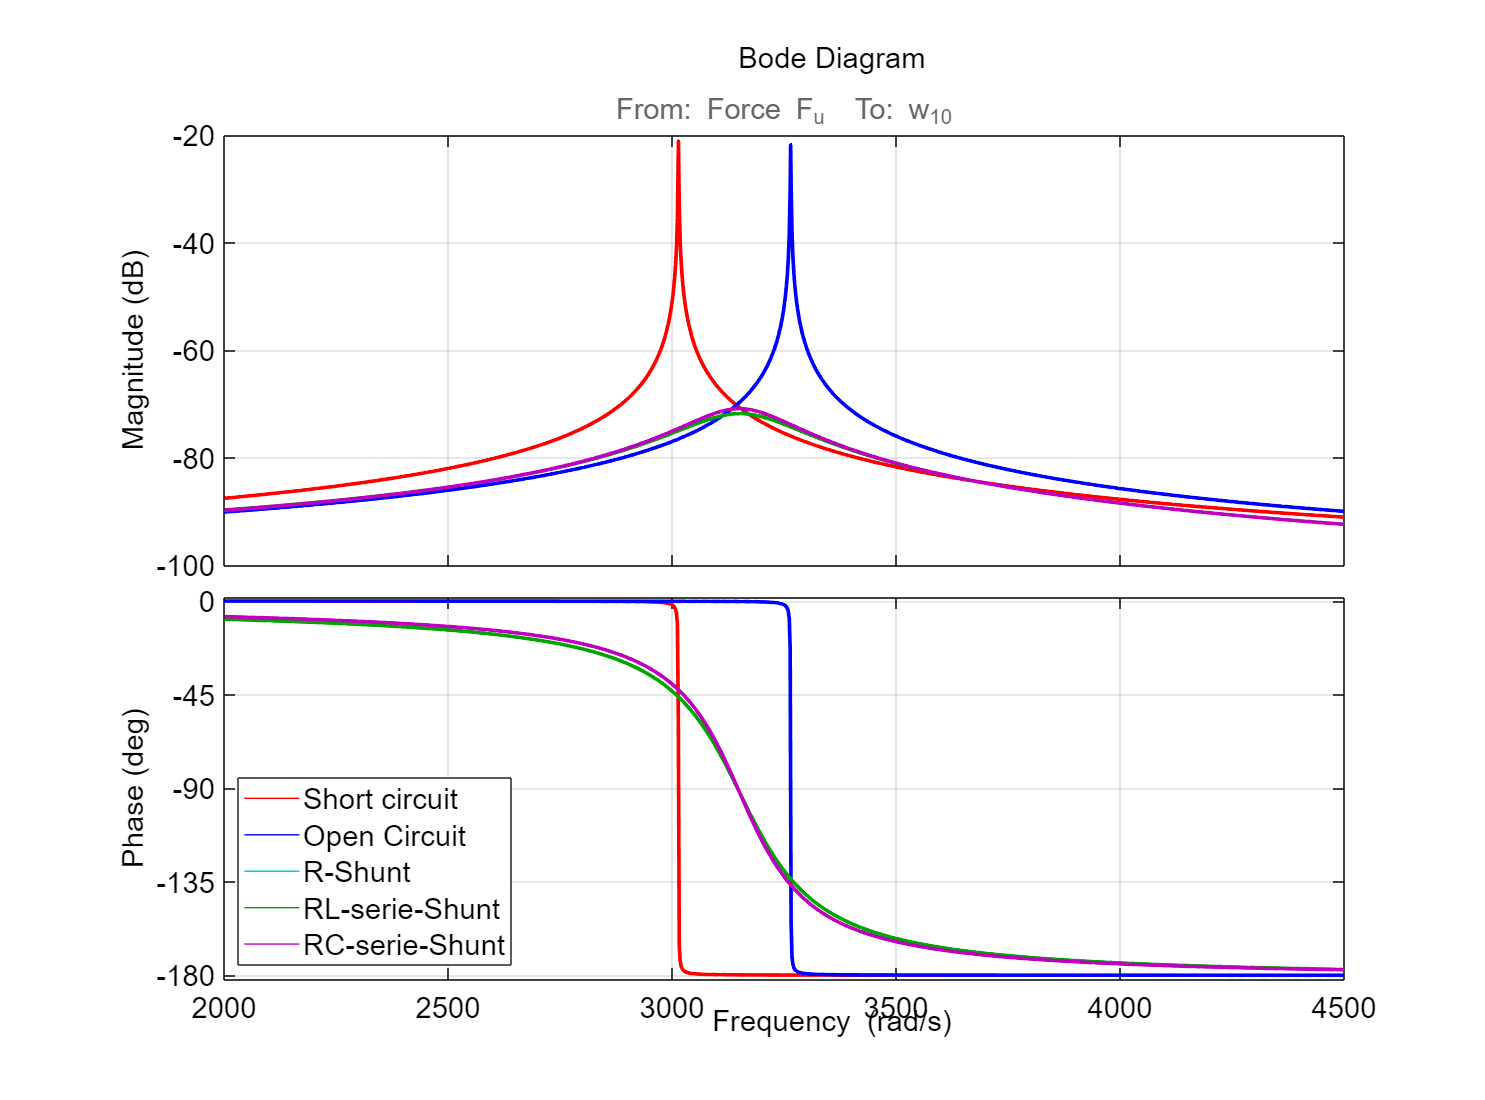

fig1 = figure;
g = bodeoptions;
g.FreqScale = 'Linear';
g.PhaseWrapping = 'on';
g.Grid = 'on';
g.XLim = {[2e3 4.5e3]};  % Frequency limits for the plot
fig1.Name = 'Bode plot';  % Name of the figure


% Plot the frequency responses for Short Circuit and Open Circuit conditions
bodeplot(Sys_sc(ouput_tf, input_tf), 'r', interval_plot,g);  % Short circuit (red)
hold on;
bodeplot(Sys_oc(ouput_tf, input_tf), 'b', interval_plot,g);  % Open circuit (blue)

% Plot the frequency responses for the various shunt conditions
bodeplot(Sys_rs_crtl_R_shunt(ouput_tf, input_tf), interval_plot,g,'c');  % Resistive shunt (cyan)
bodeplot(Sys_rs_crtl_RL_series_shunt(ouput_tf, input_tf), interval_plot,'g');  % Resistive Inductive shunt (green)
bodeplot(Sys_rs_crtl_RC_series_shunt(ouput_tf, input_tf), interval_plot,'m');  % Resistive Capactive shunt (magenta)
   
legend('Short circuit','Open Circuit','R-Shunt','RL-serie-Shunt','RC-serie-Shunt','Location', 'southwest');
hold off;

fontsize(fig1, 16, "points")
fig1.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

if save_figure_var == 1
    fig=gcf
    savefig('Figures/Bode_Sys_oc_sc_R_RL_RC_serie_shunt')
    save_fig_pdf('Figures/Bode_Sys_oc_sc_R_RL_RC_serie_shunt')
end

#### Root Locus

Create a figure for the root locus plot

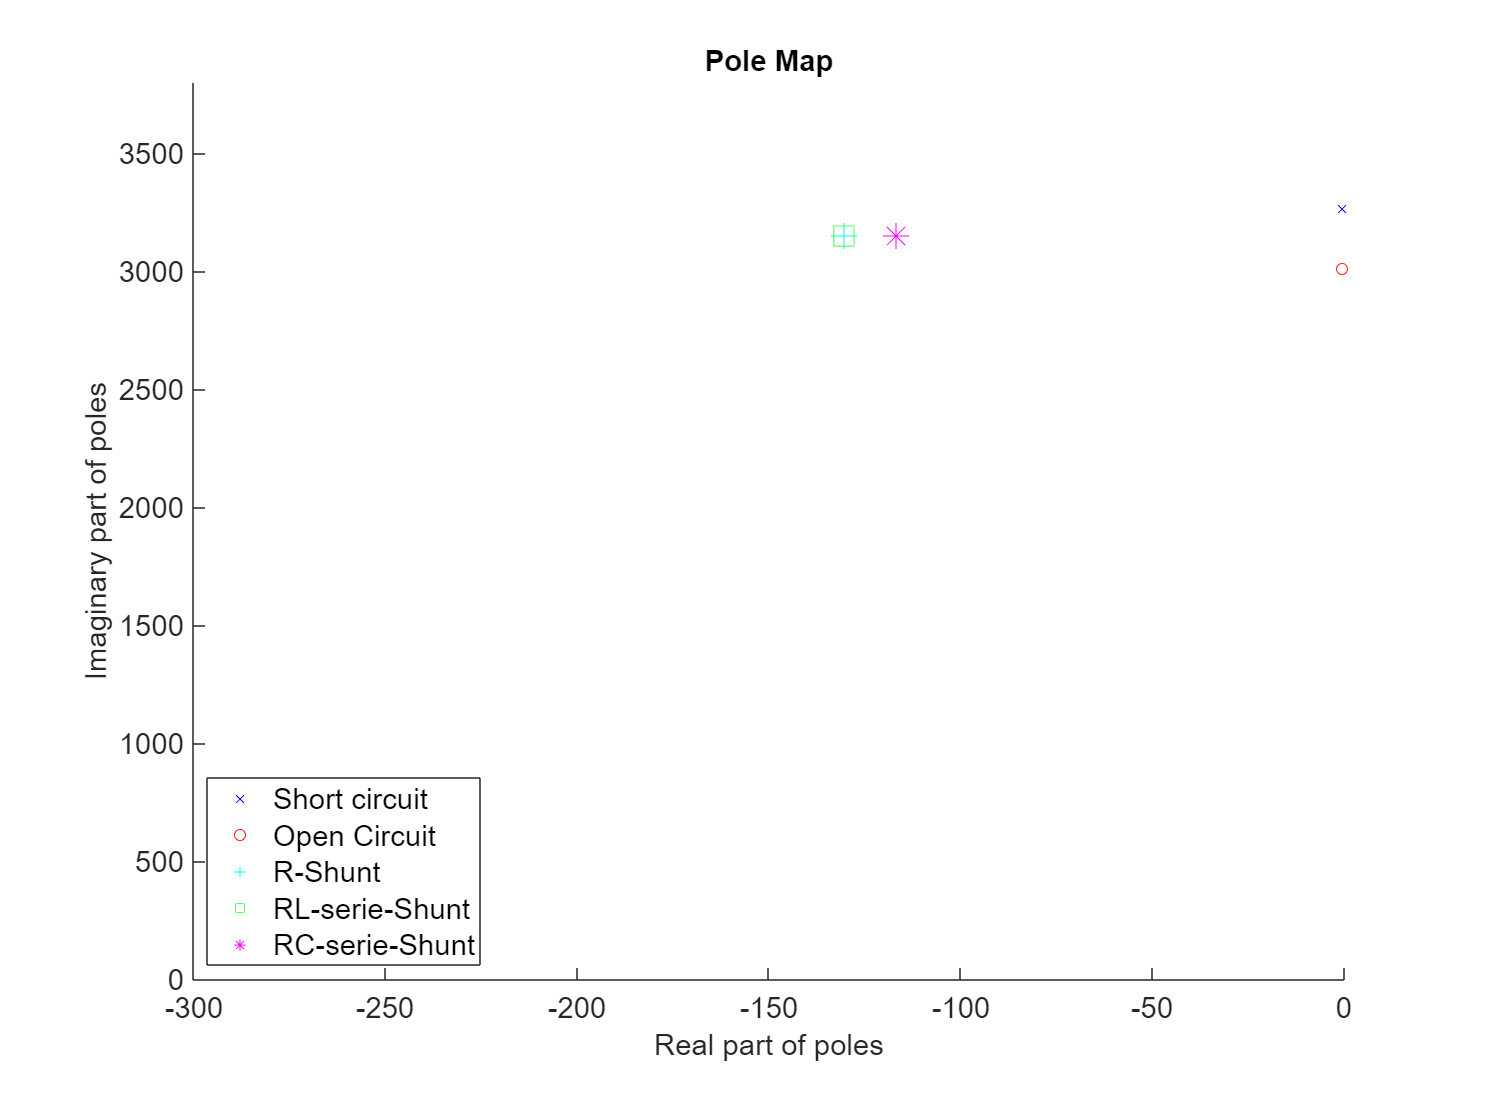

% Extract poles of the system for short circuit and open circuit
poles_sc = pole(Sys_sc(ouput_tf, input_tf));  % Short circuit poles
poles_oc = pole(Sys_oc(ouput_tf, input_tf));  % Open circuit poles

% Extract poles of the system with resistive feedback
poles_rs = pole(Sys_rs_crtl_R_shunt(ouput_tf, input_tf));
poles_rls = pole(Sys_rs_crtl_RL_series_shunt(ouput_tf, input_tf));
poles_rcs = pole(Sys_rs_crtl_RC_series_shunt(ouput_tf, input_tf));

% Define Figure to plot the poles of the system
fig2 = figure;
fig2.Name = 'Pole Map';

hold on;
% Plot poles for short circuit (red) and open circuit (blue)
scatter(real(poles_oc), imag(poles_oc), 'x', 'b');  % Blue 'x' markers
scatter(real(poles_sc), imag(poles_sc), 'o', 'r');  % Red 'o' markers

% Plot the poles for the resistive shunt case (cyan '*')
scatter(real(poles_rs), imag(poles_rs),200, '+', 'c'); 
% Plot the poles for the Resistive Inductive shunt case (green '+')
scatter(real(poles_rls), imag(poles_rls),200, 's', 'g'); 
% Plot the poles for the Resistive Capactive shunt case (magenta 's')
scatter(real(poles_rcs), imag(poles_rcs),200, '*', 'm'); 

xlim([-300 0])
xlabel('Real part of poles')
ylim([0 3800])
ylabel('Imaginary part of poles')

title(fig2.Name)

legend('Short circuit','Open Circuit','R-Shunt','RL-serie-Shunt','RC-serie-Shunt','Location', 'southwest');
hold off;

fontsize(fig2, 16, "points")
fig2.Position = [100 100 540*2 400*2];

% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

if save_figure_var == 1
    fig=gcf
    savefig('Figures/Rlocus_Sys_oc_sc_R_RL_RC_serie_shunt')
    save_fig_pdf('Figures/Rlocus_Sys_oc_sc_R_RL_RC_serie_shunt')
end

#### Time Response (Impulse Response)

Create a figure for the time response plot

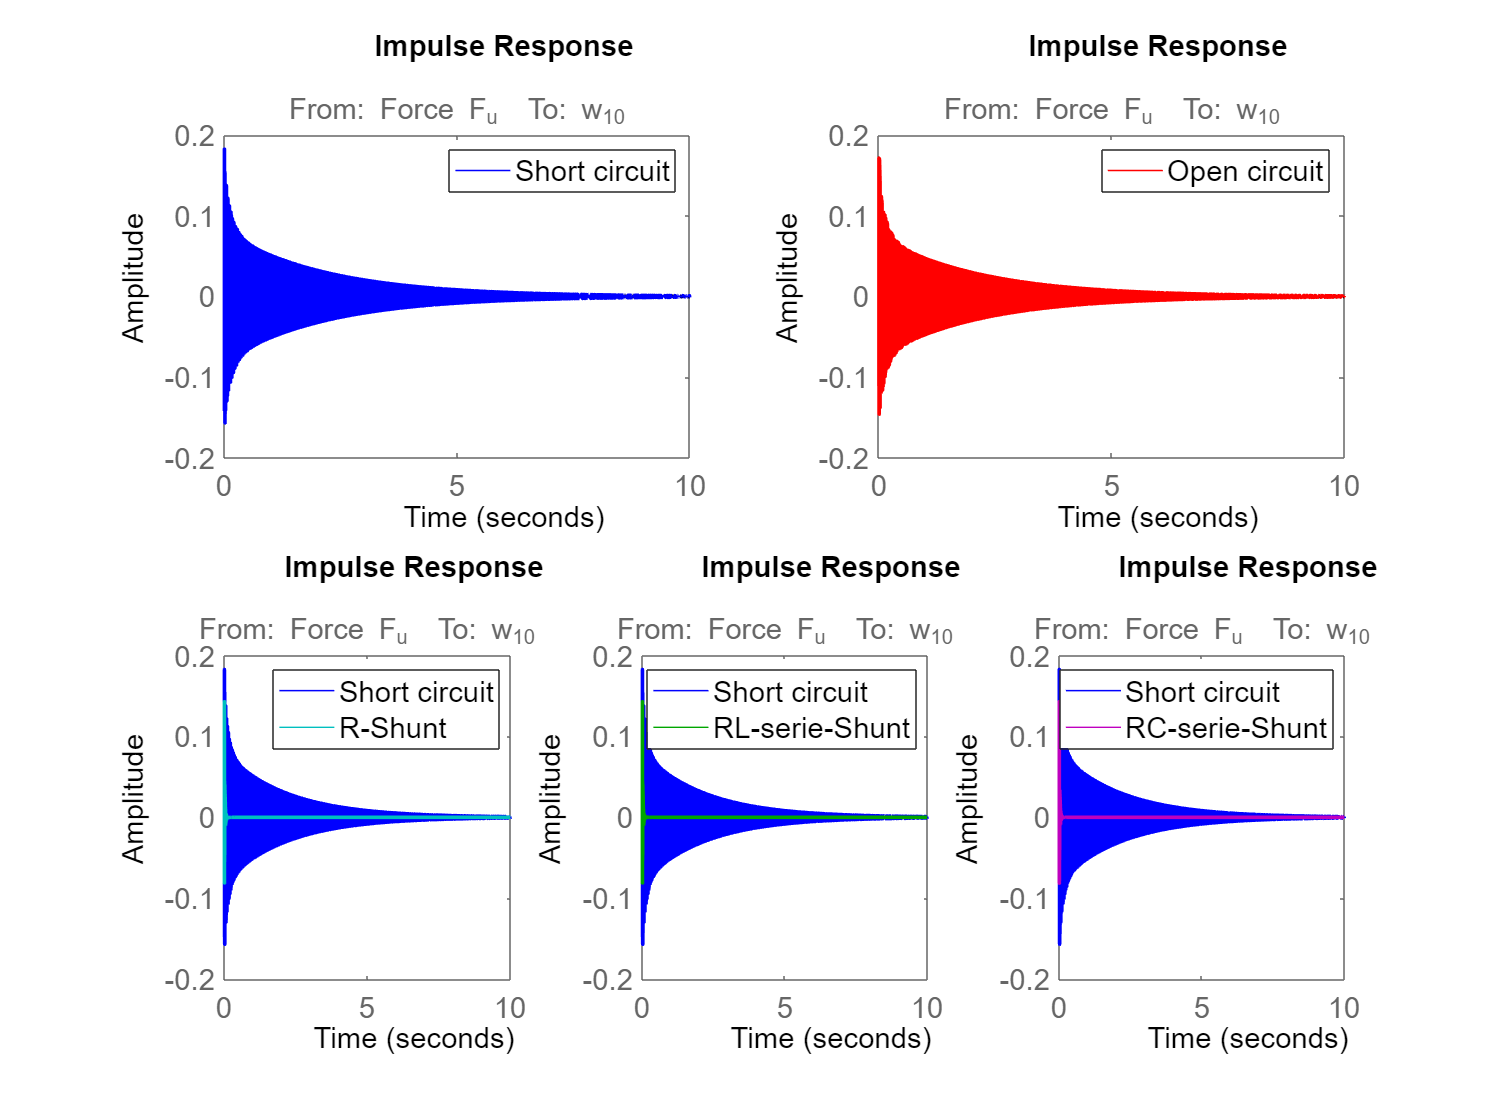

fig3 = figure;
fig3.Name = 'Impulse plot';

poles_rs = pole(Sys_rs_crtl_R_shunt(ouput_tf, input_tf));
poles_rls = pole(Sys_rs_crtl_RL_series_shunt(ouput_tf, input_tf));
poles_rcs = pole(Sys_rs_crtl_RC_series_shunt(ouput_tf, input_tf));

% Short circuit response (subplot 1)
subplot(2, 2, 1);
impulse(Sys_sc(ouput_tf, input_tf), 10, 'b');
legend('Short circuit');

% Open circuit response (subplot 2)
subplot(2, 2, 2);
impulse(Sys_oc(ouput_tf, input_tf), 10, 'r');
legend('Open circuit');
% Response for the resistive shunt case (cyan)
subplot(2, 3, 4);
hold on;
impulse(Sys_sc(ouput_tf, input_tf), 10, 'b');  % Short circuit response (blue)
impulse(Sys_rs_crtl_R_shunt(ouput_tf, input_tf), 10, 'c');  % Resistive shunt controlled response (cyan)
legend('Short circuit', 'R-Shunt');
hold off;

% Response for the Resistive Inductive shunt case (green)
subplot(2, 3, 5);
hold on;
impulse(Sys_sc(ouput_tf, input_tf), 10, 'b');  % Short circuit response (blue)
impulse(Sys_rs_crtl_RL_series_shunt(ouput_tf, input_tf), 10, 'g');  % Resistive Inductive shunt controlled response (green)
legend('Short circuit', 'RL-serie-Shunt');
hold off;

% Response for the Resistive Capactive shunt case (magenta)
subplot(2, 3, 6);
hold on;
impulse(Sys_sc(ouput_tf, input_tf), 10, 'b');  % Short circuit response (blue)
impulse(Sys_rs_crtl_RC_series_shunt(ouput_tf, input_tf), 10, 'm');  % Resistive Capactive shunt controlled response (magenta)
legend('Short circuit', 'RC-serie-Shunt');
hold off;

fontsize(fig3, 16, "points")

fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

if save_figure_var == 1
    fig=gcf
    savefig('Figures/Impulse_Sys_oc_sc_R_RL_RC_serie_shunt')
    save_fig_pdf('Figures/Impulse_Sys_oc_sc_R_RL_RC_serie_shunt')
end


## Natural Frequency Computation

The natural frequencies are computed using different methods.

### Eigenvalue Method

% Import mass and stifness matrix
load('Datas/FEM_smart_beam.mat','K_sc','M_sc','K_oc','M_oc')

Compute the first natural frequency using the eigenvalue method (from the system matrices K and M).

Case: Short Circuit (R = 0)

% Solve the eigenvalue problem for the short circuit case
[Vsc, Diag_sc] = eig(K_sc, M_sc);
% The first eigenvalue corresponds to the first natural frequency in Hz
f0_sc_ev = sqrt(Diag_sc(1, 1)) / (2 * pi());

Case: Open Circuit (R = inf, Q = 0)

% Solve the eigenvalue problem for the open circuit case
[Voc, Diag_oc] = eig(K_oc, M_oc);
% The first eigenvalue corresponds to the first natural frequency in Hz
f0_oc_ev = sqrt(Diag_oc(1, 1)) / (2 * pi());

### Poles & Zeros Method

Compute the natural frequencies from the poles and zeros of the system transfer function.

Case: Short Circuit

% Extract poles and zeros from the transfer function for the short circuit case
poles_sc = pole(Sys_sc(ouput_tf, input_tf));
zeros_sc = zero(Sys_sc(ouput_tf, input_tf));
% The first pole and zero correspond to the natural frequencies in rad/s and Hz
omega0_sc_pole = abs(poles_sc(end-1)); % Pole frequency in rad/s
f0_sc_pole = omega0_sc_pole / (2 * pi()); % Frequency in Hz
f0_sc_zero = abs(zeros_sc(end-1)) / (2 * pi()); % Zero frequency in Hz


Case: Open Circuit

% Extract poles and zeros from the transfer function for the open circuit case
poles_oc = pole(Sys_oc(ouput_tf, input_tf));
zeros_oc = zero(Sys_oc(ouput_tf, input_tf));
% The first pole and zero correspond to the natural frequencies in rad/s and Hz
omega0_oc_pole = abs(poles_oc(end-1)); % Pole frequency in rad/s
f0_oc_pole = omega0_oc_pole / (2 * pi()); % Frequency in Hz
f0_oc_zero = imag(zeros_oc(end-1)) / (2 * pi()); % Zero frequency in Hz

### Graph Reading Method

Compute the natural frequencies by reading the frequency response (Bode plot).

% Get the frequency response (magnitude, phase, and frequency) for each case
[mag_sc, phase_sc, wout_sc] = bode(Sys_sc(ouput_tf, input_tf), 'r');
[mag_oc, phase_oc, wout_oc] = bode(Sys_oc(ouput_tf, input_tf), 'b');

% Find the maximum magnitude for the short circuit, open circuit, and resistive shunt cases
[value_sc, index_sc] = max(20 * log10(abs(mag_sc)));
[value_oc, index_oc] = max(20 * log10(abs(mag_oc)));

% The first natural frequencies found in Hz from the Bode plot method
f0_sc_bode = wout_sc(index_sc) / (2 * pi());
f0_oc_bode = wout_oc(index_oc) / (2 * pi());

### Compare methods

[f0_oc_ev f0_oc_pole f0_oc_pole]

ans =   519.5132  519.5132  519.5132


[f0_sc_ev f0_sc_pole f0_sc_bode]

ans =   479.6471  479.6471  479.6471


Note: All methods (Eigenvalue, Poles & Zeros, and Graph Reading) yield the same frequency values. The eigenvalue method cannot be used with feedback gain. The graph reading method’s accuracy depends on the Bode plot discretization. The Poles and Zeros method seems to be the most reliable for computing natural frequencies.

## Optimization methods

### Litterature: Resitive Shunt (Preumont 1999 [1])

This section develops the optimization prosed by Preumont [1] to find the optimal resistance $R_{\textrm{opt}}$ that damp vibration of a given mode i.

#### Constants Definitions

- Piezoelectric capacitance

load('Datas\FEM_smart_beam.mat','Kee','d13','E_piezo_13','epsilon_33_S')
C = Kee; % Capacitance value (F)

- Electromechanical coupling factor for shear mode (d31)

d13 is the piezoelectric constant, E_piezo_13 is the Young's modulus for piezoelectric material, and epsilon_33_S is the permittivity

k31 = sqrt(d13^2 / (E_piezo_13 * epsilon_33_S)); % Electromechanical coupling factor

- Damping factor estimation based on the natural frequencies of short and open circuit

omega0_oc_pole is the natural frequency for open circuit, and omega0_sc_pole for short circuit

xsi_max_preumont = (omega0_oc_pole - omega0_sc_pole) / (2 * omega0_sc_pole); % Damping factor

#### **Optimal resistance (R_opt) **

The optimal resistance value $R_{\textrm{opt}}$ for maximum damping is given by Preumont's formula:

${\mathrm{R}}_{\textrm{opt}} =\frac{1}{\gamma_{\textrm{opt}} \left\lbrack C\left(1-k^2 \right)\right\rbrack }$ and $\gamma_{\textrm{opt}} =\Omega_i \sqrt{\frac{\Omega_i }{\omega_i \;}}$ is the feedback gain where maximum damping occurs, where $\Omega_i$ is the open circuit and $\omega_i$ the short circuit frequency of mode i, $C$is the piezoelectric capacitance and $k$is the electromechanical coupling factor.

gamma_opt = omega0_oc_pole * sqrt(omega0_oc_pole / omega0_sc_pole); % Feedback gain for max damping

Calculate the optimal resistance R_opt using Preumont's method

R_opt_preumont = 1 / (gamma_opt * C * (1 - k31^2)); % Optimal resistance for maximum damping

In this example, a resitive shunt is implemented on the transducers. The objective of the optimization is to increase the damping of the first mode. 

% Define the range of resistive values (R) for the feedback control
R_value_param = 10.^[log10(1e5):1/2:log10(1e7)];
Z = R_value_param;  % Resistive values for feedback control

% Set up parameters for the feedback control
feedin = 1;  % Moment applied (input)
feedout = 1;  % Output is the charge q

% Minimum value for comparison in the optimization loop
value_min = 1000;

#### **Bode response**

% Create a figure for plotting the results
fig4=figure;

% Plot the frequency responses for Short Circuit and Open Circuit conditions
bodeplot(Sys_sc(ouput_tf, input_tf), 'r', interval_plot, g);  % Short circuit (red)
hold on;
       

% Loop through each value of R to compute the frequency response with resistive shunt
for i = 1:length(R_value_param)
    % Define the feedback control for the given R value
    Controle = s * Z(i);
    
    % Compute the system response with feedback control (resistive shunt)
    Sys_rs_contr_R = feedback(Sys_rs, Controle, feedin, feedout);
    
    % Compute magnitude, phase, and frequency response
    [mag_rs_c_R, phase_rs_c_R, wout_rs_c_R] = bode(Sys_rs_contr_R(ouput_tf, input_tf), 'k');
    
    % Find the maximum value of the magnitude response and its corresponding frequency
    [value_rs_c_R, index_rs_c_R] = max(20*log10(abs(mag_rs_c_R)));
    f0_rs_c_R(i) = wout_rs_c_R(index_rs_c_R) / (2*pi);  % Convert to Hz
    
    % Plot the frequency response for this R value
    bodeplot(Sys_rs_contr_R(ouput_tf, input_tf), interval_plot,'c');  % Resistive shunt (cyan)
    
    % Optimization to find the R value that minimizes the magnitude
    if (value_min > max(20*log10(abs(mag_rs_c_R))))
        value_min = max(20*log10(abs(mag_rs_c_R)));
        R_opt_estim = Z(i);  % Optimal R value
        freq_opt = f0_rs_c_R(i);  % Frequency corresponding to the optimal R
    end
end

bodeplot(Sys_oc(ouput_tf, input_tf), 'b', interval_plot, g);  % Open circuit (blue)

Controle_R_series_shunt=s * R_opt_preumont;
Sys_rs_contr_R_series = feedback(Sys_rs,Controle_R_series_shunt,feedin,feedout);
bodeplot(Sys_rs_contr_R_series(ouput_tf, input_tf),interval_plot,g,'m')


% Controle = s * R_opt_preumont;
% % Compute the system response with feedback control (resistive shunt)
% Sys_rs_contr_R = feedback(Sys_rs, Controle, feedin, feedout);
% % Plot the frequency response for this R value
% bodeplot(Sys_rs_contr_R(ouput_tf, input_tf), interval_plot, 'm');  % Resistive shunt (cyan)

% Add a legend to the plot
Namelegend=['Short circuit' 'R_{shunt}='+ string(round(R_value_param,0)) 'Open Circuit' 'R_{opt}='+ string(round(R_opt_preumont,0))];
legend(Namelegend, 'Location', 'northwest');
hold off;

% Display note about the zoom on the first resonance frequency
disp(['Note: A zoom was made around the first resonance frequency of the system.']);

Note: A zoom was made around the first resonance frequency of the system.


disp(['The maximum damping is reached with R close to: ', num2str(R_opt_estim)]);

The maximum damping is reached with R close to: 316227.766


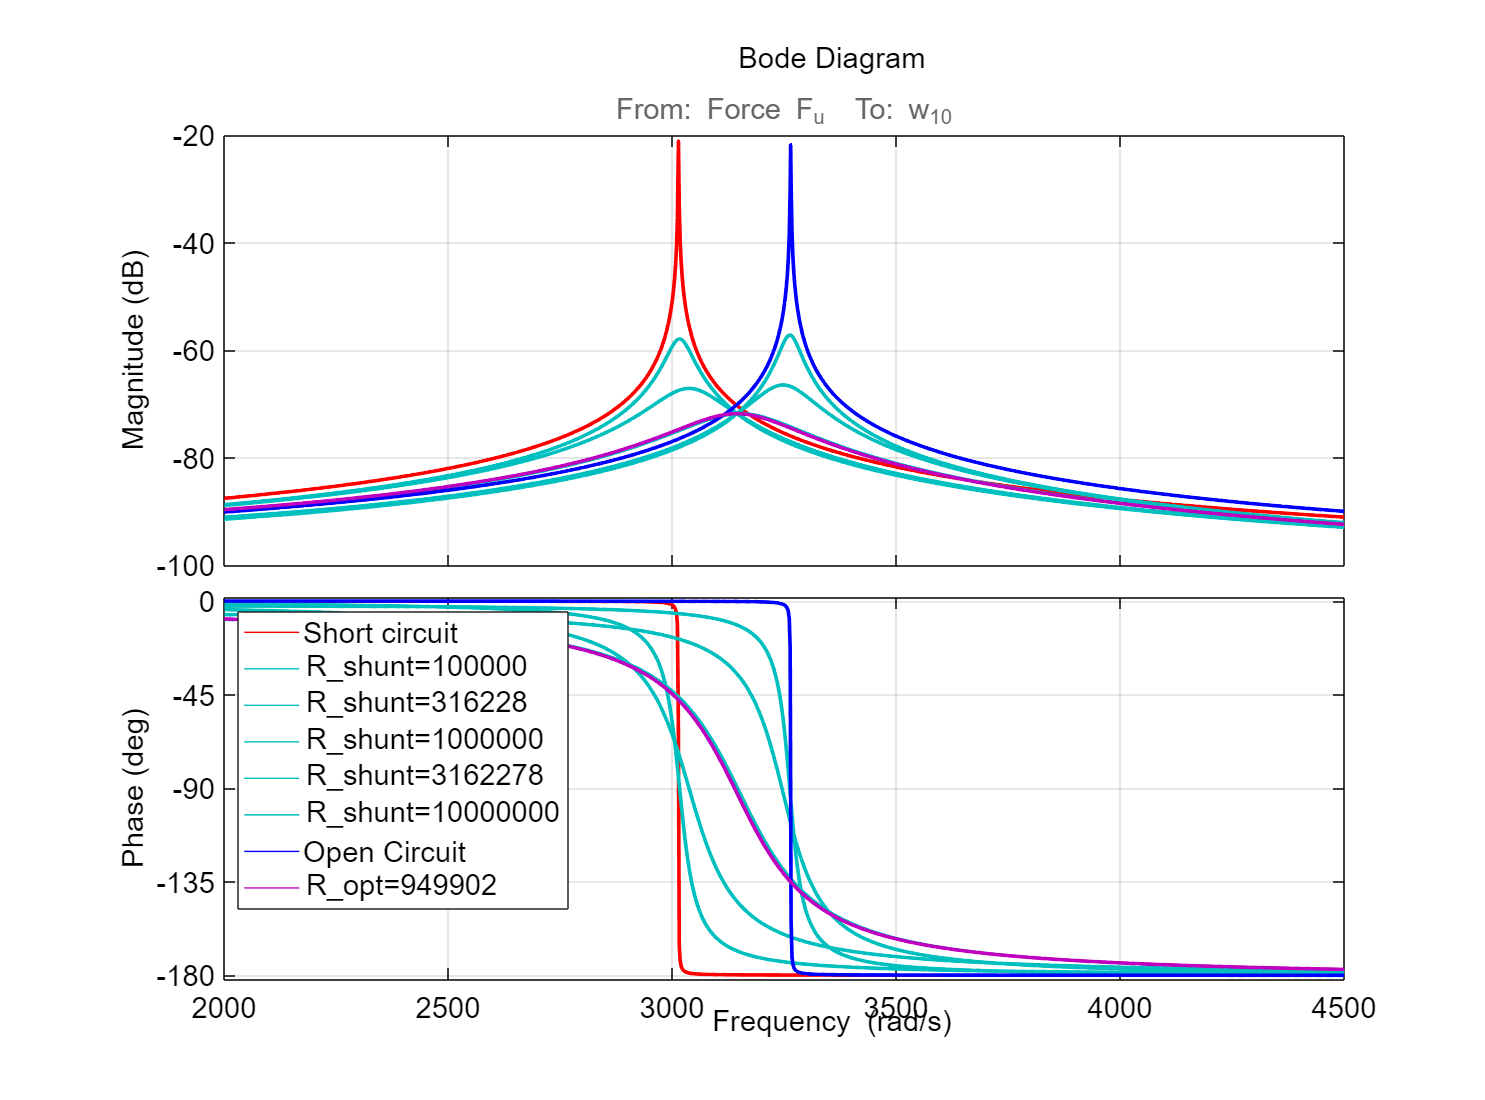

fontsize(fig4, 16, "points")
fig4.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

Note: The short-circuit configuration corresponds to low resistance values ($R=0\;$), whereas the open-circuit configuration corresponds to high resistance values ($R=\infty$). The optimal resistance optain is mode dependant. 

if save_figure_var == 1
    savefig('Bode_R_shunt_param_var_oc_sc')
    save_fig_pdf('Bode_R_shunt_param_var_oc_sc')
end

#### **Root Locus**

Create a figure for the root locus plot

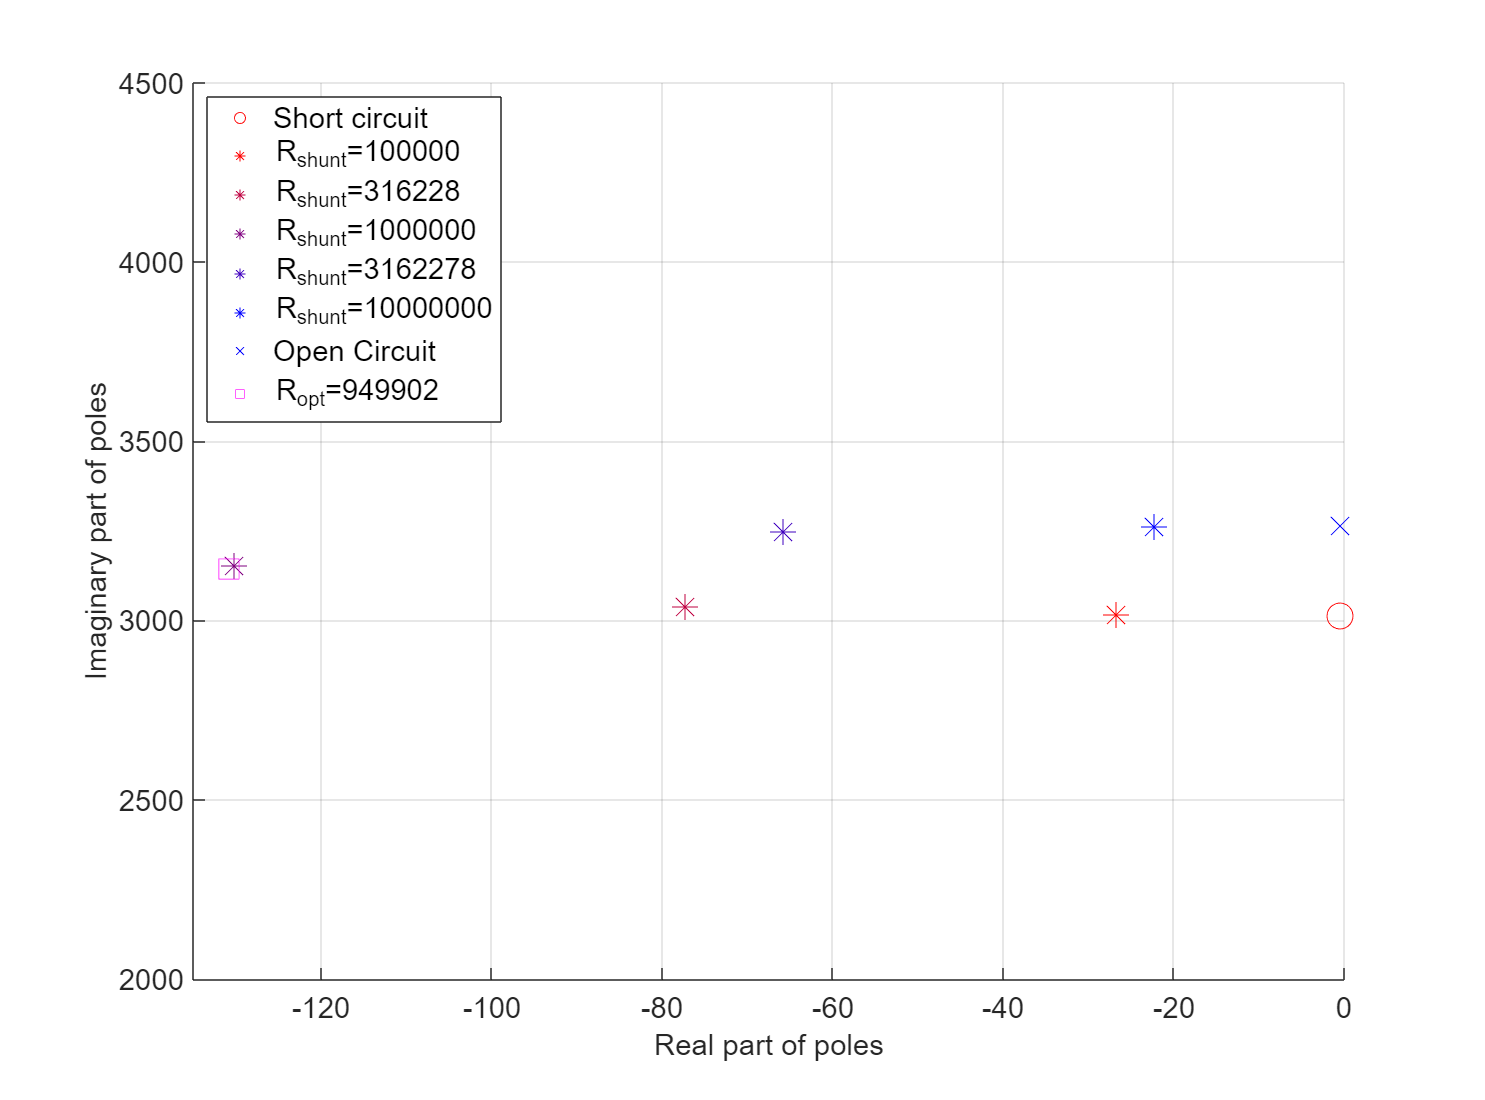

fig5 = figure;
fig5.Name = 'Root locus plot';
% Number of colors in the transition
num_colors = length(R_value_param);

% Generate RGB values for red and blue
red_rgb = [1, 0, 0]; % Red color (RGB)
blue_rgb = [0, 0, 1]; % Blue color (RGB)

% Interpolate between red and blue to create the color array
color_array = zeros(num_colors, 3);
for i = 1:num_colors
    color_array(i, :) = (i-1) / (num_colors-1) * blue_rgb + (num_colors-i) / (num_colors-1) * red_rgb;
end

hold on;
% Plot poles for short circuit (red) and open circuit (blue)
poles_sc = pole(Sys_sc(ouput_tf, input_tf));  % Short circuit poles
scatter(real(poles_sc), imag(poles_sc),200, 'o', 'r');  % Red 'o' markers
% Loop through each R value and plot the poles for the resistive shunt case
for i = 1:length(R_value_param)
    % Define feedback control with resistive feedback
    Controle = s * Z(i);
    Sys_rs_contr_R = feedback(Sys_rs, Controle, feedin, feedout);
    
    % Extract poles of the system with resistive feedback
    poles_rs = pole(Sys_rs_contr_R(ouput_tf, input_tf));
    
    % Plot the poles for the resistive shunt case (cyan '*')
    scatter(real(poles_rs), imag(poles_rs),200,color_array(i,:), '*'); 
end
poles_oc = pole(Sys_oc(ouput_tf, input_tf));  % Open circuit poles
scatter(real(poles_oc), imag(poles_oc),200, 'x', 'b');  % Blue 'x' markers

poles_R_shunt = pole(Sys_rs_contr_R_series(ouput_tf, input_tf));  % Open circuit poles
scatter(real(poles_R_shunt), imag(poles_R_shunt),200, 's', 'm');  % Blue 'x' markers


% Add legend and axis labels
Namelegend=['Short circuit' 'R_{shunt}='+ string(round(R_value_param,0)) 'Open Circuit' 'R_{opt}='+ string(round(R_opt_preumont,0))];
legend(Namelegend, 'Location', 'northwest');
xlim([-135 0.01]);
ylim([interval_plot(1), interval_plot(end)]);
xlabel('Real part of poles');
ylabel('Imaginary part of poles');
grid on;
hold off;
fontsize(fig5, 16, "points")
fig5.Position = [100 100 540*2 400*2];

Note: In this figure you can see the variation of damping with resistance as the pole of the first mode becomes more negative. The optimum resistance is obtained for the largest angle with the imaginary axis, where the damping is maximum.

% Save the figure if the variable save_figure_var is set to 1
if save_figure_var == 1
    savefig('Rlocus_R_shunt_param_var_oc_sc');  % Save as .fig
    save_fig_pdf('Rlocus_R_shunt_param_var_oc_sc');  % Save as .pdf
end

### Litterature: R-L Series Shunt (Hagood 1991 [2] and Park 2003 [3])

This section develops the optimization prosed by Hagood [2] and Park [3] to find the optimal resistance $R_{\textrm{opt}}$ and inductance in serie $L_{\textrm{opt}}$ that damp vibration of a given mode i. Two methods are proposed using transfer functions or pole placements

% Import piezoelectric transducer properties
load('Datas/FEM_smart_beam.mat','l_piezo','L_piezo','h_piezo','epsilon_33_S','d13','E_piezo_13')

% Get the poles and zeros for short circuit case
poles_sc = pole(Sys_sc(ouput_tf, input_tf));
zeros_sc = zero(Sys_sc(ouput_tf, input_tf));

% Calculate the natural frequency of short circuit in Hz
omega0_sc_pole = abs(min(poles_sc)) / (2 * pi()); 
omega0_oc_pole = abs(min(poles_oc)) / (2 * pi()); 

Unrecognized function or variable 'poles_oc'.

#### Constants Definitions

- Piezoelectric capacitance

Cpi = l_piezo * L_piezo * epsilon_33_S / h_piezo;

-  Electromechanical coupling factor: material property in case of shear mode (d31): $k_{13} =\frac{d_{31}^2 }{s^E \epsilon^T \;\;}$

k31_hagood=sqrt((omega0_oc_pole^2-omega0_sc_pole^2)/omega0_sc_pole^2)

#### **Optimal resistance (R_opt) and inductance (L_opt): **Transfer function Method

% Optimal parameters from transfer function consideration
delta_opt_TF = sqrt(1 + k31_hagood^2);
r_opt_TF = sqrt(2) * k31_hagood / (1 + k31_hagood^2);

% Calculate the optimal resistance in transfer function form
R_opt_Hagood_tf = r_opt_TF / (Cpi * omega0_sc_pole);

% Calculate the optimal angular frequency for transfer function
omega_e = delta_opt_TF * omega0_sc_pole;

% Calculate the optimal inductance using Hagood's method for transfer function
L_opt_Hagood_tf = 1 / (omega_e^2 * Cpi);

#### **Optimal resistance (R_opt) and inductance (L_opt): **Pole Placement Method

% Optimal parameters from pole placement considerations
delta_opt_pp = 1 + k31_hagood^2;
r_opt_pp = 2 * sqrt(k31_hagood^2 / (1 + k31_hagood^2)^3);

% Calculate the optimal resistance using Hagood's method (pole placement)
R_opt_Hagood_pp = r_opt_pp / (Cpi * omega0_sc_pole);

omega_e = delta_opt_pp * omega0_sc_pole;
L_opt_Hagood_pp = 1 / (omega_e^2 * Cpi);

%Chose the optimal resitance between the two methods
% R_opt_Hagood=R_opt_Hagood_tf;
R_opt_Hagood=R_opt_Hagood_pp; 


#### Bode Response

% Plot for various resistance values
fig6=figure;
% Plot the frequency responses for Short Circuit and Open Circuit conditions
bodeplot(Sys_sc(ouput_tf, input_tf), 'r', interval_plot,g);  % Short circuit (red)
hold on;
bodeplot(Sys_oc(ouput_tf, input_tf), 'b', interval_plot,g);  % Open circuit (blue)

Controle_RL_series_tf=s*R_opt_Hagood_tf+s^2*L_opt_Hagood_tf;
Sys_rs_contr_RL_series_tf = feedback(Sys_rs,Controle_RL_series_tf,feedin,feedout);
bodeplot(Sys_rs_contr_RL_series_tf(ouput_tf, input_tf),interval_plot,g,'g')
Controle_RL_series_pp=s*R_opt_Hagood_pp+s^2*L_opt_Hagood_pp;
Sys_rs_contr_RL_series_pp = feedback(Sys_rs,Controle_RL_series_pp,feedin,feedout);
bodeplot(Sys_rs_contr_RL_series_pp(ouput_tf, input_tf),interval_plot,g,'m')

r = [5, 2, 0.25, 0.15, 0.05];
for i = 1:length(r)
    R = r(i) / (Cpi * omega0_sc_pole);
    Controle = s * R + s^2 * L_opt_Hagood_tf;
    Sys_rs_contr_R = feedback(Sys_rs, Controle, feedin, feedout);
    bode(Sys_rs_contr_R(ouput_tf, input_tf), interval_plot, g, 'c');
end

% Add legend for the plot
legend('Short circuit', 'Open Circuit', 'RL serie Shunt Hagood tf', 'RL serie Shunt Hagood pp', 'RL serie Shunt (R var)' , 'Location', 'northwest');
grid on

fontsize(fig6, 16, "points")
fig6.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

Note: The RL-serie shunt acts like a secondary system with a behavior similar to a tuned mass damper (TMD).

% Save the final figure if specified
if save_figure_var == 1
    savefig('Figures/Bode_RLserie_shunt_param_var_oc_sc');
    save_fig_pdf('Figures/Bode_RLserie_shunt_param_var_oc_sc');
end

### Litterature: RCneg serie Shunt (Collet 2011 [4])

This section develops the optimization prosed by Collet et al. [4]  to find the optimal negative capacitance $C_{\textrm{opt}}$ with resistance $R_{\textrm{opt}}$ from Hagood [2] in serie that damp vibration of a given mode i.

**Optimal negative capacitance (C_opt): **

load('Datas\FEM_smart_beam.mat','epsilon_33_T')
Cp_T=l_piezo*h_piezo*epsilon_33_T/h_piezo;
C_opt_Collet=-Cp_T

C_opt_Collet = -5.8879e-10

#### Bode Response

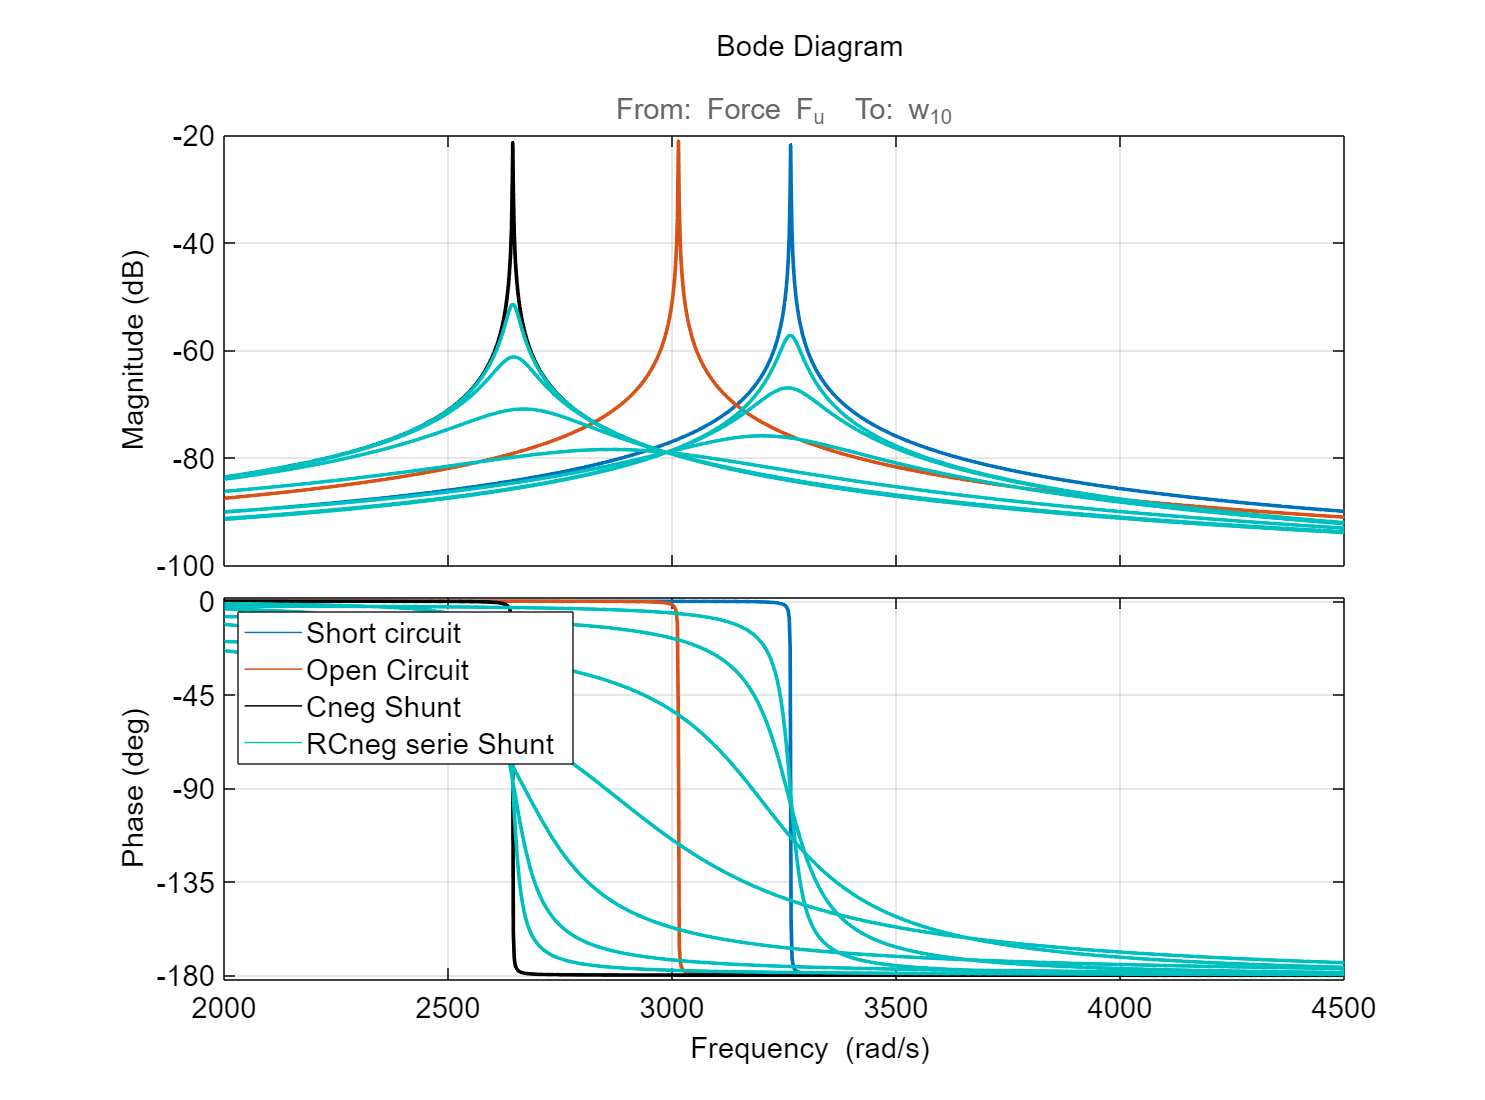

fig7=figure;
hold on
bode(Sys_oc(ouput_tf, input_tf),interval_plot)
bode(Sys_sc(ouput_tf, input_tf),interval_plot)

Controle=1/C_opt_Collet;
Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
bode(Sys_rs_contr_R(ouput_tf, input_tf),interval_plot, g, 'k')

R_value_param = 10.^[log10(1e4):1/2:log10(1e7)];

for i=1:length(R_value_param)
    Controle=R_value_param(i)*s+1/C_opt_Collet;
    Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
    bode(Sys_rs_contr_R(ouput_tf, input_tf),interval_plot, g, 'c')
end

legend('Short circuit', 'Open Circuit', 'Cneg Shunt', 'RCneg serie Shunt', 'Location', 'northwest');

fontsize(fig7, 16, "points")
fig7.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

% Save the final figure if specified
if save_figure_var == 1
    savefig('Figures/Bode_RCneg_parallel_shunt_param_var_oc_sc');
    save_fig_pdf('Figures/Bode_RCneg_parallel_shunt_param_var_oc_sc');
end

#### Root Locus

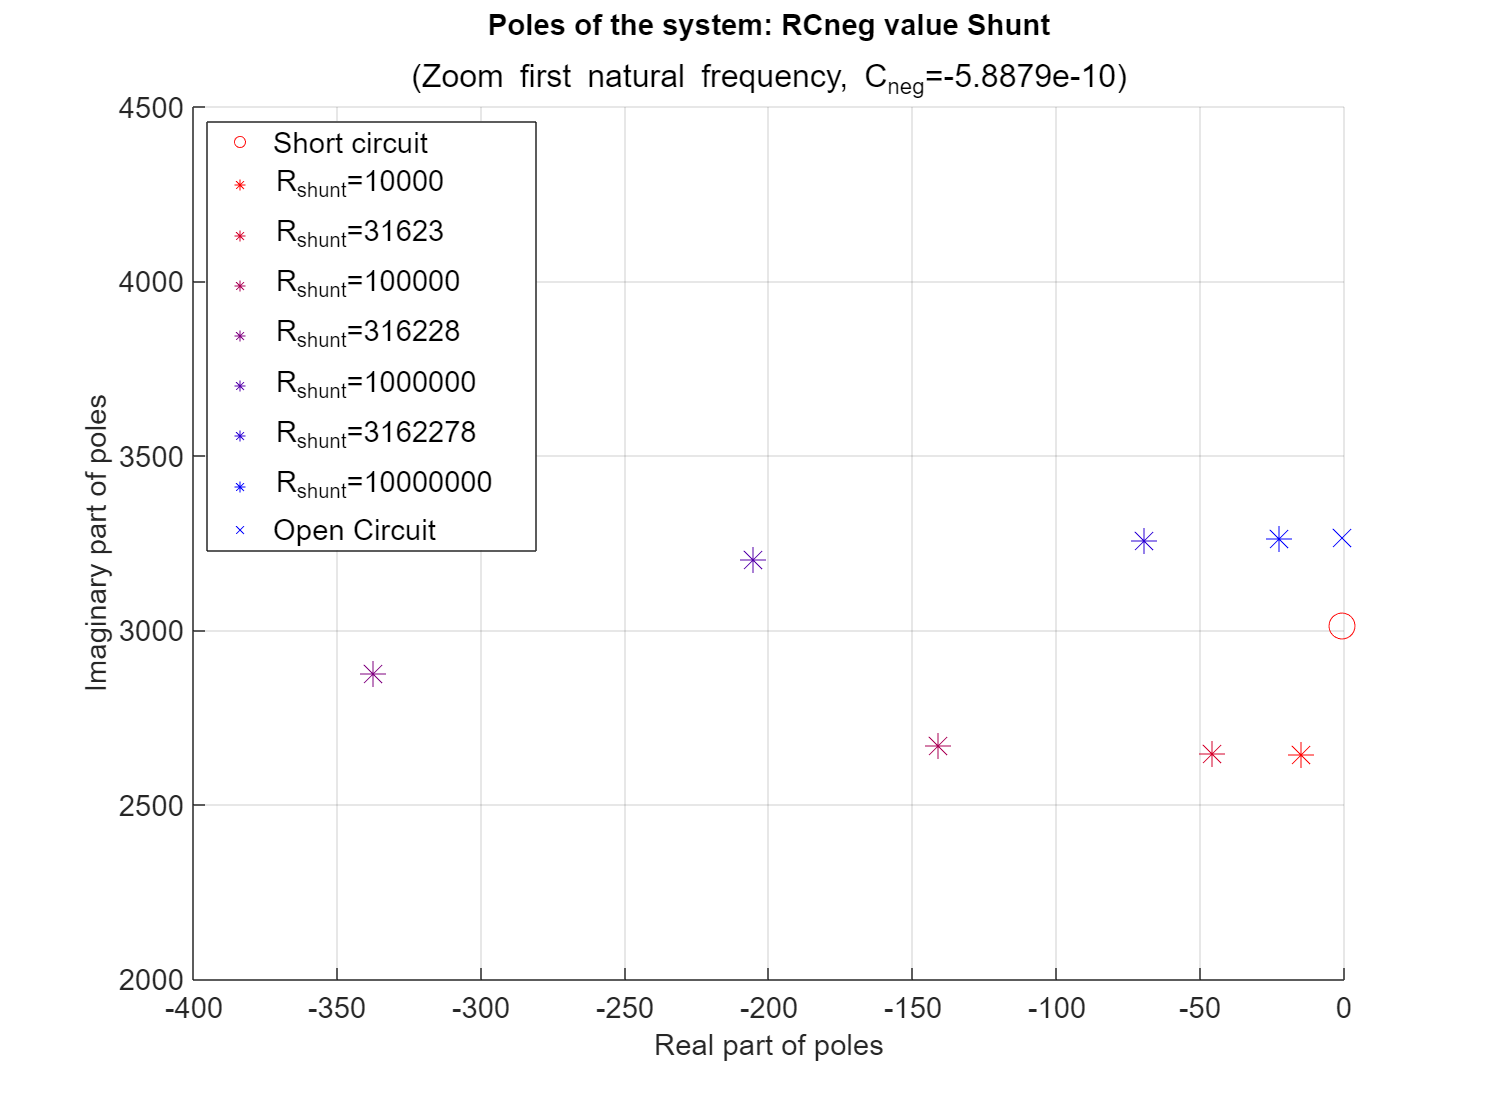

fig8=figure;
hold on
% Number of colors in the transition
num_colors = length(R_value_param);

% Generate RGB values for red and blue
red_rgb = [1, 0, 0]; % Red color (RGB)
blue_rgb = [0, 0, 1]; % Blue color (RGB)

% Interpolate between red and blue to create the color array
color_array = zeros(num_colors, 3);
for i = 1:num_colors
    color_array(i, :) = (i-1) / (num_colors-1) * blue_rgb + (num_colors-i) / (num_colors-1) * red_rgb;
end
poles_sc=pole(Sys_sc(ouput_tf, input_tf));
scatter(real(poles_sc),imag(poles_sc),200,'o','r')
for i=1:length(R_value_param)
    Controle=s*R_value_param(i)+1/C_opt_Collet;
    Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
    poles_rs=pole(Sys_rs_contr_R(ouput_tf, input_tf));
    real_pole(i)=real(poles_rs(end-2));
    imag_pole(i)=imag(poles_rs(end-2));
    scatter(real(poles_rs),imag(poles_rs),200,color_array(i, :),'*')
end
poles_oc=pole(Sys_oc(ouput_tf, input_tf));
scatter(real(poles_oc),imag(poles_oc),200,'x','b')
Namelegend=['Short circuit' 'R_{shunt}='+ string(round(R_value_param,0)) 'Open Circuit'];
legend(Namelegend,'Location','northwest')
xlim([-400 0.01])
ylim([interval_plot(1) interval_plot(end)])
xlabel('Real part of poles')
ylabel('Imaginary part of poles')
title('Poles of the system: RCneg value Shunt')
subtitle('(Zoom first natural frequency, C_{neg}='+string((C_opt_Collet))+')')
grid("on")
hold off
fontsize(fig8, 16, "points")
fig8.Position = [100 100 540*2 400*2];

Note: The Negative capacitance shunt acts like the piezoelectric coupling coefficient is increased.

% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth
% Save the final figure if specified
if save_figure_var == 1
    savefig('Figures/Rlocus_RCneg_shunt_param_var_oc_sc');
    save_fig_pdf('Figures/Rlocus_RCneg_shunt_param_var_oc_sc');
end

### Litterature: RLC serie and parallel Shunt (Berardengo 2018 [5])

This section develops the optimization prosed by Berardengo et al. [5]  to find the optimal shunt considering different arrangements of RLC circuit.

#### Step 1: Calculate the optimal capacitance (C_opt) 

The formula for capacitance optimization considers the piezoelectric dimensions and material properties.

C_pi=l_piezo * h_piezo * epsilon_33_T / h_piezo ;
beta = 0.8865 %1/1.09;

beta = 0.8865

C_opt_Ber = C_pi / beta;

Where:

l_piezo: Length of the piezoelectric patch (m)

h_piezo: Thickness of the piezoelectric patch (m)

epsilon_33_T: Permittivity of the piezoelectric material in the 33-direction (F/m)

The factor 1.09 is a coefficient used in the optimization (Berardengo 2018).

Calculate the equivalent capacitance in series configuration

C_eq_Ber =  C_pi*C_opt_Ber/(C_opt_Ber-C_pi)

C_eq_Ber = 5.1876e-09

#### Step 2: Calculate the optimal inductance (L_opt) 

omega_opt_serie=omega0_oc_pole

omega_opt_serie = 519.5132

L_opt_Ber_serie=1/(omega_opt_serie^2*C_eq_Ber)

L_opt_Ber_serie = 714.2357

omega_opt_parallel=sqrt((3*(omega0_sc_pole)^2-(omega0_oc_pole)^2)/2)

omega_opt_parallel = 458.4158

L_opt_Ber_parallel=1/(omega_opt_parallel^2*C_eq_Ber)

L_opt_Ber_parallel = 917.3088

#### Step 3: Calculate the optimal inductance (R_opt) and chose the serie or parallel

xi_opt_serie=sqrt(3)/2*sqrt((omega0_oc_pole^2-omega0_sc_pole^2)/(omega0_oc_pole^2+omega0_sc_pole^2))

xi_opt_serie = 0.2444

R_opt_Ber_serie=2*xi_opt_serie*sqrt(L_opt_Ber_serie/C_eq_Ber)

R_opt_Ber_serie = 1.8141e+05

xi_opt_parallel=sqrt(3)/2*sqrt((omega0_oc_pole^2-omega0_sc_pole^2)/(3*omega0_sc_pole^2-omega0_oc_pole^2))

xi_opt_parallel = 0.2666

R_opt_Ber_parallel=1/(2*xi_opt_serie)*sqrt(L_opt_Ber_parallel/C_opt_Ber)

R_opt_Ber_parallel = 2.4038e+06

#### Bode plot

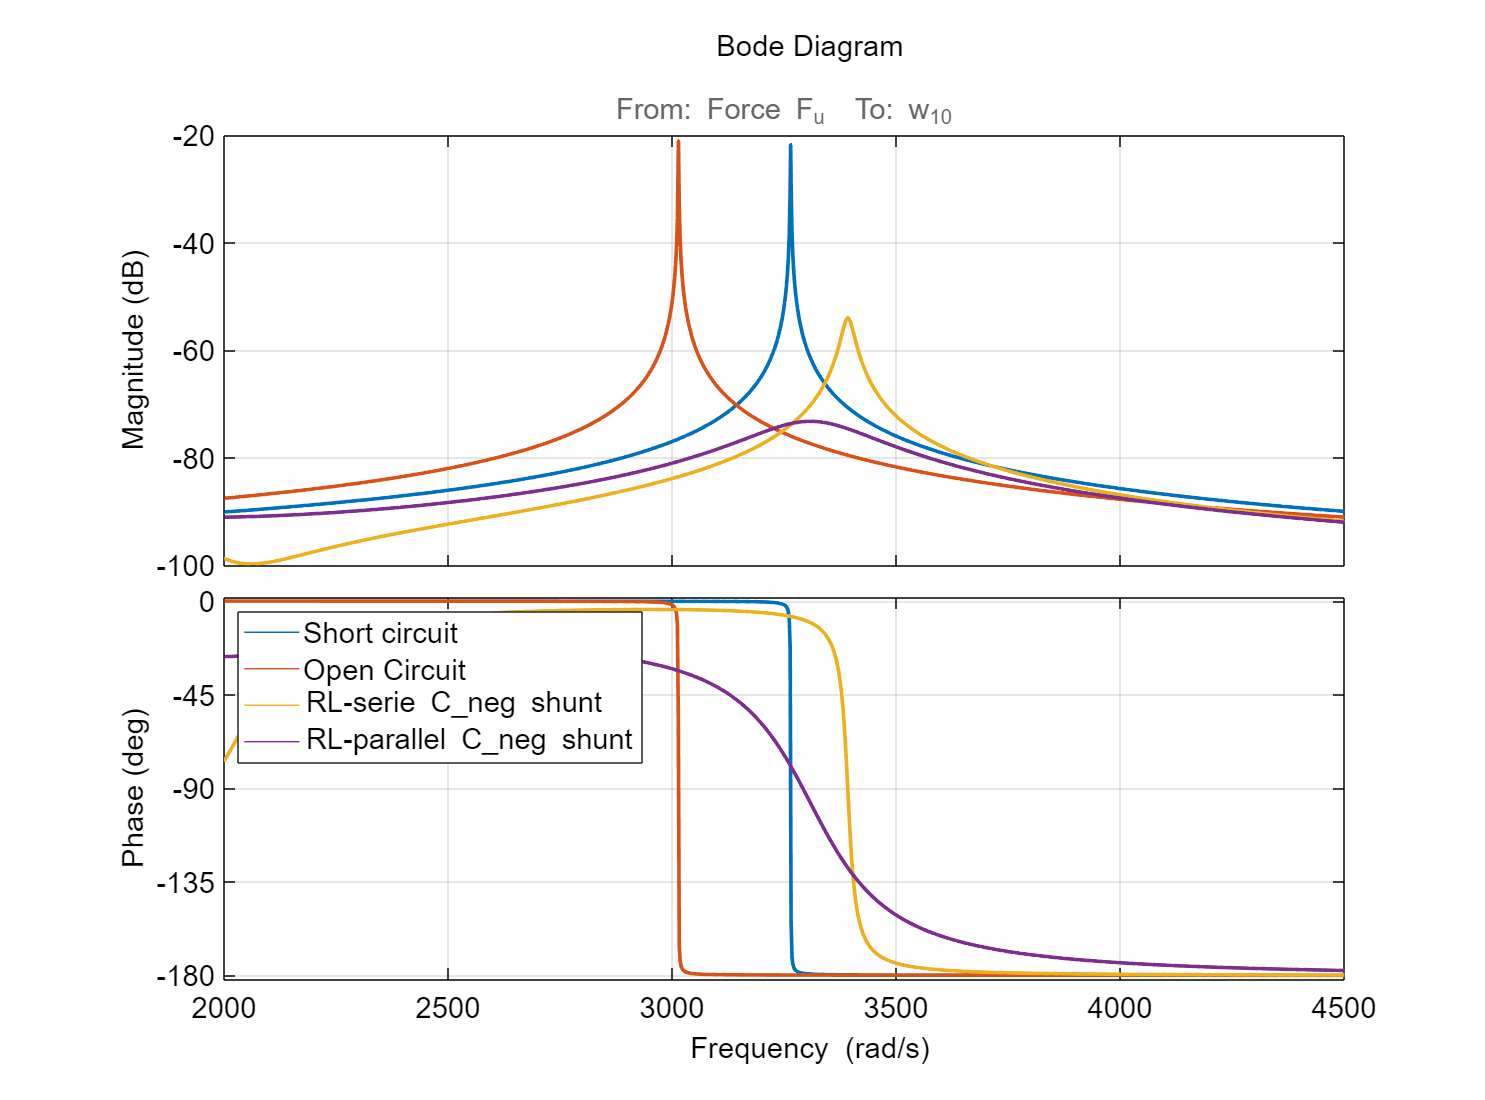

fig9=figure;
hold on
bode(Sys_oc(ouput_tf, input_tf),interval_plot)
bode(Sys_sc(ouput_tf, input_tf),interval_plot)

Controle_RLC_series_shunt = (s * R_opt_Ber_serie + s^2 * L_opt_Ber_serie)-1/C_eq_Ber;
Sys_rs_contr_RLC_serie = feedback(Sys_rs,Controle_RLC_series_shunt,feedin,feedout);
bode(Sys_rs_contr_RLC_serie(ouput_tf, input_tf),interval_plot, g)

Controle_RLC_parallel_shunt = s^2 * L_opt_Ber_parallel*R_opt_Ber_parallel/(L_opt_Ber_parallel*s+R_opt_Ber_parallel)-1/C_eq_Ber;
Sys_rs_contr_RLC_parallel = feedback(Sys_rs,Controle_RLC_parallel_shunt,feedin,feedout);
bode(Sys_rs_contr_RLC_parallel(ouput_tf, input_tf),interval_plot, g)


legend('Short circuit', 'Open Circuit', 'RL-serie C_{neg} shunt', 'RL-parallel C_{neg} shunt', 'Location', 'northwest');

fontsize(fig9, 16, "points")
fig9.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

% Save the final figure if specified
if save_figure_var == 1
    savefig('Figures/Bode_RL_serie_parallel_shunt_oc_sc');
    save_fig_pdf('Figures/Bode_RL_serie_parallel_shunt_oc_sc');
end

## Conclusion

### Plot Figures

#### Bode plot

Compare the influence of each optimal shunt on the system response: 

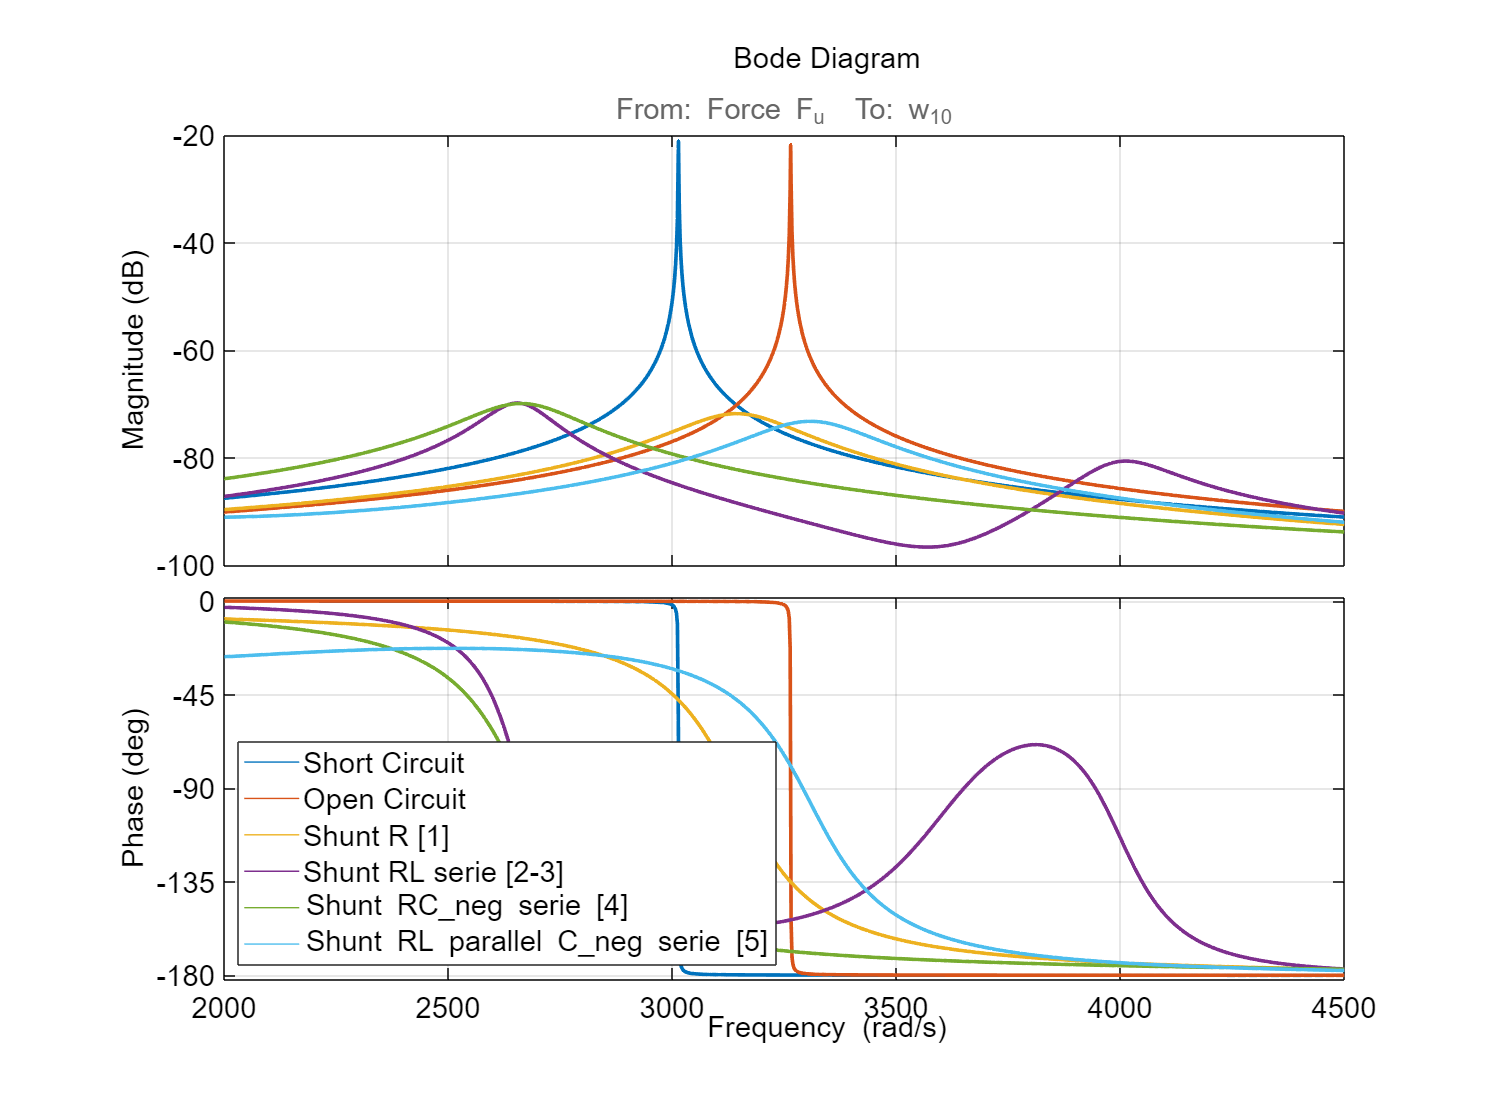

interval_plot=[2000:0.01:4500];
fig10=figure;
hold on
bodeplot(Sys_sc(ouput_tf, input_tf),interval_plot,g)
bodeplot(Sys_oc(ouput_tf, input_tf),interval_plot,g)
Controle_R_series_shunt=s * R_opt_preumont;
Sys_rs_contr_R_series = feedback(Sys_rs,Controle_R_series_shunt,feedin,feedout);
bodeplot(Sys_rs_contr_R_series(ouput_tf, input_tf),interval_plot,g)
Controle_RL_series=s*R_opt_Hagood+s^2*L_opt_Hagood_tf;
Sys_rs_contr_RL_series = feedback(Sys_rs,Controle_RL_series,feedin,feedout);
bodeplot(Sys_rs_contr_RL_series(ouput_tf, input_tf),interval_plot,g)
Controle_RCneg_series=s*R_opt_Hagood+1/C_opt_Collet;
Sys_rs_contr_RCneg_series = feedback(Sys_rs,Controle_RCneg_series,feedin,feedout);
bodeplot(Sys_rs_contr_RCneg_series(ouput_tf, input_tf),interval_plot,g)
Controle_RLC_parallel_shunt = s^2 * L_opt_Ber_parallel*R_opt_Ber_parallel/(L_opt_Ber_parallel*s+R_opt_Ber_parallel)-1/C_eq_Ber;
Sys_rs_contr_RLC_parallel = feedback(Sys_rs,Controle_RLC_parallel_shunt,feedin,feedout);
bode(Sys_rs_contr_RLC_parallel(ouput_tf, input_tf),interval_plot, g)


% Plot Bode plot for short circuit and open circuit
g.XLim = {[2e3, 4.5e3]};

legend('Short Circuit','Open Circuit', ...
    'Shunt R [1]', ...
    'Shunt RL serie [2-3]', ...
    'Shunt RC_{neg} serie [4]', ...
    'Shunt RL parallel C_{neg} serie [5]', ...
    'Location','southwest')

fontsize(fig10, 16, "points")
fig10.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

% Save the final figure if specified
if save_figure_var == 1
    savefig('Figures/Bode_compare_all_shunt_oc_sc');
    save_fig_pdf('Figures/Bode_compare_all_shunt_oc_sc');
end


#### Root Locus

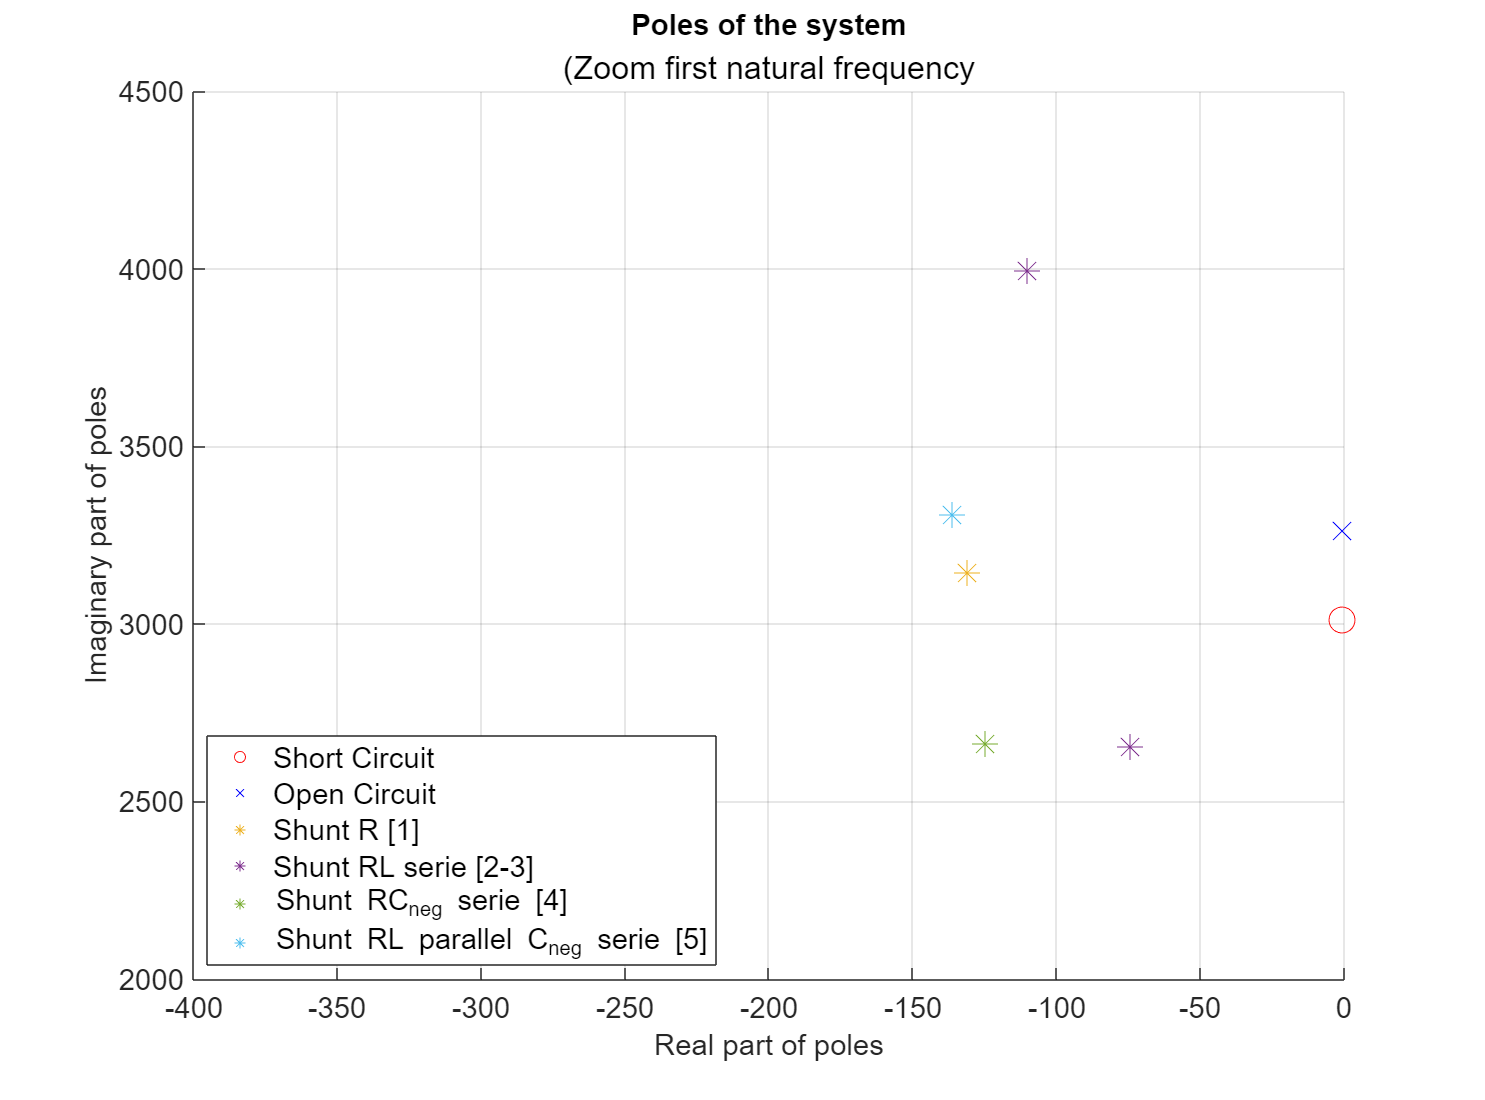

fig11=figure;
hold on
poles_sc=pole(Sys_sc(ouput_tf, input_tf));
scatter(real(poles_sc),imag(poles_sc),200,'o','r')
poles_oc=pole(Sys_oc(ouput_tf, input_tf));
scatter(real(poles_oc),imag(poles_oc),200,'x','b')
poles_R_series_shunt=pole(Sys_rs_contr_R_series(ouput_tf, input_tf));
scatter(real(poles_R_series_shunt),imag(poles_R_series_shunt),200,'*')
poles_RL_series_shunt=pole(Sys_rs_contr_RL_series(ouput_tf, input_tf));
scatter(real(poles_RL_series_shunt),imag(poles_RL_series_shunt),200,'*')
poles_RCneg_series_shunt=pole(Sys_rs_contr_RCneg_series(ouput_tf, input_tf));
scatter(real(poles_RCneg_series_shunt),imag(poles_RCneg_series_shunt),200,'*')
poles_RLC_parallel_shunt=pole(Sys_rs_contr_RLC_parallel(ouput_tf, input_tf));
scatter(real(poles_RLC_parallel_shunt),imag(poles_RLC_parallel_shunt),200,'*')

legend('Short Circuit','Open Circuit', ...
    'Shunt R [1]', ...
    'Shunt RL serie [2-3]', ...
    'Shunt RC_{neg} serie [4]', ...
    'Shunt RL parallel C_{neg} serie [5]', ...
    'Location','southwest')
xlim([-400 0.01])
ylim([interval_plot(1) interval_plot(end)])
xlabel('Real part of poles')
ylabel('Imaginary part of poles')

title('Poles of the system')
subtitle('(Zoom first natural frequency')
grid("on")
hold off

fontsize(fig11, 16, "points")
fig11.Position = [100 100 540*2 400*2];


% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth
% Save the final figure if specified
if save_figure_var == 1
    savefig('Figures/Rlocus_compare_all_shunt_oc_sc');
    save_fig_pdf('Figures/Rlocus_compare_all_shunt_oc_sc');
end


### Comments

For the resistive shunt, the theoretical optimum values obtained by Preumont [1] and Hagood [2] give similar, highly damped results for the beam's first bending mode. The RL series shunt is more attenuating than the Resistive shunt on the beam's first bending mode but it induces a peak splitting around the target frequency. The RC shunt is more effective in the frequency range, providing the best damping factor. It is possible to use various combinations of resistive, inductive and capacitive shunts in series or in parallel as described by Berardengo et al. [5] on a cantilever beam coupled to a pair of piezoelectric patches. The use of negative capacitive shunts in series provides both stability and damping performance for vibration damping and, in some cases, resonance cancellation. Literature highlights the possibility of using passive control on piezoelectric structure using various electrical shunt to do vibration damping. Optimal damping can be obtained with analytical formulation, but requires a relevant knowledge about the structure material and behavior.

## Bibliography

[1] P. André, "Vibration Control of Active Structures : An Introduction", 1999-04, *Meccanica* , Vol. 34, No. 2, Springer International Publishing, DOI:[10.1023/A:1004398914135](http://dx.doi.org/10.1023/A:1004398914135)

[2] N. W. Hagood, and A. von Flotow, "Damping of Structural Vibrations with PiezoelectricMaterials and Passive Electrical Networks", Journal of Sound and Vibration**, **1991, Vol. 146, p. 243-268, DOI: [https://doi.org/10.1016/0022-460X(91)90762-9](https://doi.org/10.1016/0022-460X(91)90762-9)

[3] C. H. Park, "Dynamics modellingof beams with shuntedpiezoelectric elements, Journal of Sound and Vibration"**, **2003, Vol. 268, p. 115-129, DOI: [https://doi.org/10.1016/S0022-460X(02)01491-8](https://doi.org/10.1016/S0022-460X(02)01491-8)

[4]  M.Collet, M. Ouisse, K.A. Cunefare, M. Ruzzene, B. Beck, L. Airoldi, F. Casadei, "Vibroacoustic Energy Diffusion Optimization in Beams and Plates by Means of Distributed Shunted Piezoelectric Patches", Vibration and Structural Acoustics Analysis, Springer, Dordrecht, 2011, p. 265-302, DOI: [https://doi.org/10.1007/978-94-007-1703-9_10](https://doi.org/10.1007/978-94-007-1703-9_10)

[5]  M. Berardengo, S. Manzoni, O. Thomas, M. Vanali, "Piezoelectric resonant shunt enhancement by negative capacitances: Optimisation, performance and resonance cancellation", Journal of Intelligent Material Systems and Structures. 2018, Vol. 29. DOI: [https://doi.org/10.1177/1045389X18770874](https://doi.org/10.1177/1045389X18770874)